# NR NTN PDSCH Throughput

This example shows how to measure the physical downlink shared channel (PDSCH) throughput of a 5G New Radio (NR) link in a non-terrestrial network (NTN) channel, as defined by the 3GPP NR standard. The example implements the PDSCH and downlink shared channel (DL-SCH). The transmitter model includes PDSCH demodulation reference signals (DM-RS) and PDSCH phase tracking reference signals (PT-RS). The example supports NTN narrowband and NTN tapped delay line (TDL) propagation channels.

## Introduction

This example measures the PDSCH throughput of a 5G link, as defined by the 3GPP NR standards [1], [2], [3], [4].

The example models these 5G NR features:

- DL-SCH transport channel coding

- Multiple codewords, dependent on the number of layers

- PDSCH, PDSCH DM-RS, and PDSCH PT-RS generation

- Variable subcarrier spacing and frame numerologies

- Normal and extended cyclic prefix

- NTN narrowband and NTN TDL propagation channel models

Other features of the simulation are:

- PDSCH precoding using singular value decomposition (SVD).

- Cyclic prefix orthogonal frequency division multiplexing (CP-OFDM) modulation.

- Slot-wise and non-slot-wise PDSCH and DM-RS mapping.

- Timing synchronization and channel estimation.

- A single bandwidth part (BWP) across the whole carrier.

- Doppler pre-compensation at the transmitter, and Doppler compensation at the receiver.

- Optional hybrid automatic repeat request (HARQ) support up to 32 processes.

- Optional power amplifier modeling with and without memory. The power amplifier modeling with memory requires RF Toolbox™.

- Optional static and time-varying propagation delay modeling.

The figure shows the implemented processing chain. For clarity, DM-RS and PT-RS generation are omitted.

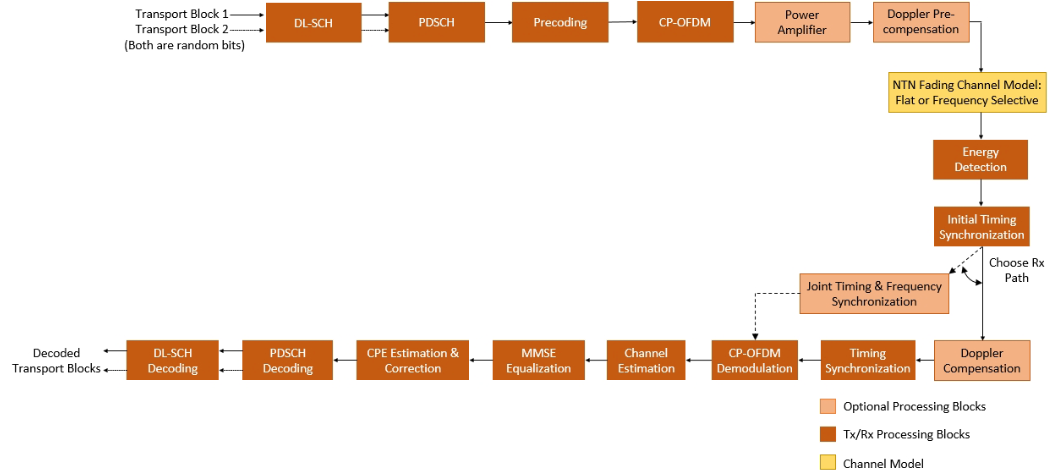

For a more detailed explanation of the steps implemented in this example, see [Model 5G NR Communication Links](docid:5g_gs#mw_b41487f2-4e53-412e-83ff-b77bd3984819) and [DL-SCH and PDSCH Transmit and Receive Processing Chain](docid:5g_gs#mw_5441cb0f-86ed-4038-8735-d0a50ea68f60).

This example supports wideband and subband precoding. You determine the precoding matrix by using SVD and averaging the channel estimate across all PDSCH PRBs either in the allocation (for wideband precoding) or in the subband.

To reduce the total simulation time, you can use Parallel Computing Toolbox™ to execute the range of transmit power values of the transmit power loop in parallel.

## Configure Simulation Length, Transmitter, and Receiver

Set the length of the simulation in terms of the number of 10 ms frames. By default, the example uses 2 frames, but a large number of 10 ms frames is necessary to produce meaningful throughput results. Set the range of transmit power values to simulate. The transmitter power is defined as the power of the time-domain waveform before performing Doppler pre-compensation and includes the gain of the power amplifier. The receiver includes its noise figure and the antenna temperature. The noise figure models the receiver internal noise, and the antenna temperature models the input noise. This receiver specifies the noise per antenna element.

simParameters = struct;                   % Create simParameters structure to
                                          % contain all key simulation parameters
simParameters.NFrames = 1;                % Number of 10 ms frames
simParameters.TxPower = 60:2:70;                % Transmit power (dBm)
simParameters.RxNoiseFigure = 6;          % Noise figure (dB)
simParameters.RxAntennaTemperature = 290; % Antenna temperature (K)

Set the `displaySimulationInformation` variable to `true` to display information about the throughput simulation at each transmit power point.

displaySimulationInformation = true;

## Power Amplifier Configuration

The example supports both memory and memoryless power amplifier modeling. To model the power amplifier with memory, this example requires RF Toolbox™.

To configure a memory or memoryless power amplifier nonlinearity, use the `enablePA` variable. The input signal that is passed to the power amplifier is a normalized signal with the maximum signal amplitude.

### Memoryless Power Amplifier

You can select one of these memoryless power amplifier models (`paModel`), as defined in Annex A of TR 38.803.

- 2.1 GHz Gallium Arsenide (GaAs)

- 2.1 GHz Gallium Nitride (GaN)

- 28 GHz complementary metal-oxide semiconductor (CMOS)

- 28 GHz GaN

Alternatively, you can set `paModel` to `Custom` and use `paCharacteristics` variable to define the memoryless power amplifier characteristics as a matrix with three columns. The first column defines the input power in dBm. The second column defines the output power in dBm. The third column defines the output phase in degrees. When you set the `paCharacteristics` variable to empty and the `paModel` to `Custom`, this example uses a 2.1 GHz laterally-diffused metal-oxide semiconductor (LDMOS) Doherty-based amplifier.

When you set `paModel` to a value other than `Custom`, the memoryless nonlinearity applied to the waveform follows this equation for power amplifiers.


$$y_P \left(n\right)=\sum_{k\;\in {\;K}_p } a_k \;x\left(n\right)\;{\left|x\left(n\right)\right|}^{2k}$$


In this equation,

- $y_P \left(n\right)$ is the output signal.

- $x\left(n\right)$ is the input signal.

- $K_p$ is the set of polynomial degree(s).

- $a_k$ is the polynomial coefficient.

### Power Amplifier With Memory

The nonlinearity with memory applied to the waveform follows this memory polynomial equation.


$$y_P \left(n\right)=\sum_{m=0}^{M-1} \sum_{k=0}^{K-1} a_{\textrm{mk}} \;x\left(n-m\right)\;{\left|x\left(n-m\right)\right|}^k \;$$


In this equation,

- $M$is the memory-polynomial depth.

- $K$is the memory-polynomial degree.

- $a_{\textrm{mk}}$ is the polynomial coefficient.

To model the power amplifier with memory, set the `hasMemory` variable to `true` and use the `coefficients` variable to provide the polynomial coefficients. The `coefficients` variable is a matrix with number of rows corresponding to memory-polynomial depth and number of columns corresponding to memory-polynomial degree. When you set `coefficients` to empty, a default value is applied.

By default, the example sets `enablePA` to `false`.

enablePA = false;                 % true or false
hasMemory = false;                % true or false
paModel = "2.1GHz GaAs"; % "2.1GHz GaAs", "2.1GHz GaN", "28GHz CMOS", "28GHz GaN", or "Custom"
paCharacteristics = [];         % Lookup table as empty or a matrix with columns: Pin (dBm) | Pout (dBm) | Phase (degrees)
coefficients = [];              % Memory polynomial coefficients

When you set `enablePA` is `true`, use the `scaleFactor` variable to modify the maximum input signal amplitude to excite the power amplifier nonlinearity. `scaleFactor` controls the operating region of the power amplifier and is applied for each transmit antenna. You can also use the `scaleFactor` variable to set power backoff. For example, to provide a power backoff of 3 dB to a signal passed through the power amplifier, set `scaleFactor` to -3. Ensure the input signal is within the characterization range of the power amplifier model.

When `scaleFactor` is empty, the example uses a default value of -35 dB in these cases. 

- `hasMemory` is `false`, `paModel` is `Custom`, and `paCharacteristics` is empty.

- `hasMemory` is `true` and `coefficients` is empty.

In all other cases, when you set `scaleFactor` to empty, the example uses a default value of 0 dB.

scaleFactor = []; % Amplitude scaling, in dB

## Doppler Compensation Configuration

The example supports two Doppler compensation configurations: one at the transmitter and the other at the receiver. For compensation at the transmitter, enable `DopplerPreCompensator`. Setting the `DopplerPreCompensator` field to `true` accounts for Doppler due to satellite movement by applying Doppler pre-compensation to the transmitted waveform. For compensation at the receiver, enable the `RxDopplerCompensator` field. Setting the `RxDopplerCompensator` field to `true` estimates and compensates the Doppler shift of the received waveform, using cyclic prefix and reference signals. When you set the `RxDopplerCompensator` field to `true`, you can select the technique for estimating and compensating Doppler at the receiver using the `RxDopplerCompensationMethod` field. The `RxDopplerCompensationMethod` field supports: 

- Independent time-frequency synchronization (`independent time-freq`), where the receiver compensates for frequency or Doppler shift first and then compensates for timing offset.

- Joint time-frequency synchronization (`joint time-freq`), where the receiver compensates for both frequency and time at once.

By default, this example assumes the user equipment (UE) is at the satellite beam center.  To model a UE in the satellite beam other than the beam center (as shown in the next image) and to apply a Doppler shift common to all the UEs in a beam ($f_{d,\textrm{common}}$), you can use the `PreCompensationDopplerShift` field. When the `PreCompensationDopplerShift` field is empty, the example uses the Doppler shift due to satellite at the UE ($f_{d,\textrm{sat}}$) as $f_{d,\textrm{common}}$. This example assumes $f_{d,\textrm{common}}$ is known. To observe the link performance when `PreCompensationDopplerShift` field is nonempty, both `DopplerPreCompensator` field and `RxDopplerCompensator` field must be set to `true`. Enabling `DopplerPreCompensator` compensates $f_{d,\textrm{common}}$, while enabling `RxDopplerCompensator` compensates the residual satellite Doppler shift ($f_{d,\textrm{sat}}$-$f_{d,\textrm{common}}$) along with Doppler shift due to UE movement.

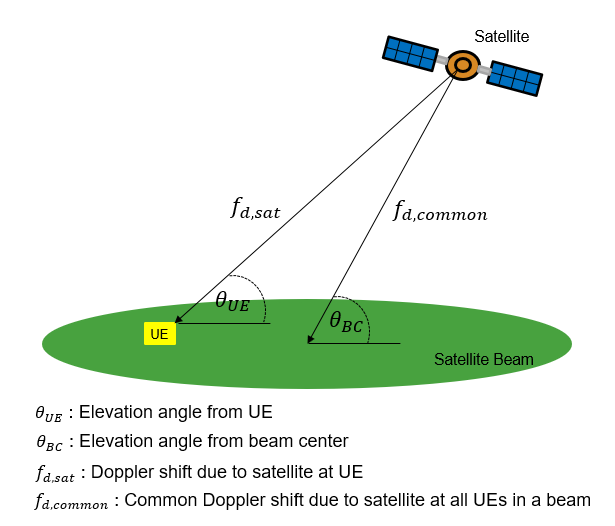

simParameters.DopplerPreCompensator = true;
simParameters.PreCompensationDopplerShift = [];                   % In Hz
simParameters.RxDopplerCompensator = false;
simParameters.RxDopplerCompensationMethod = "independent time-freq";
% The example uses below fields to estimate Doppler shift, when
% RxDopplerCompensator is set to true and RxDopplerCompensationMethod is
% set to joint time-freq.
% Set the search range of Doppler shift in Hz [MIN,MAX]
simParameters.FrequencyRange = [-50e3 50e3];
% Set the search range resolution of Doppler shift in Hz
simParameters.FrequencyResolution = 1e3;

## Initial Timing Synchronization Algorithm Selection

Select an algorithm for initial timing synchronization. 

- Auto correlation (`auto corr`): The receiver performs timing synchronization using auto correlation with PDSCH DM-RS.

- Differential correlation (`diff corr`): The receiver performs timing synchronization using differential correlation with PDSCH DM-RS.

- Joint time-frequency technique (`joint time-freq`): The receiver performs timing synchronization by compensating for initial frequency and initial timing at once.

simParameters.InitialTimingSynchronization = "joint time-freq";
% The example uses below fields to perform initial synchronization, when
% InitialTimingSynchronization is set to joint time-freq.
% Set the initial search range of Doppler shift in Hz [MIN,MAX]
simParameters.InitialFrequencyRange = [-50e3 50e3];
% Set the initial search range resolution of Doppler shift in Hz
simParameters.InitialFrequencyResolution = 1e3;

## Carrier and PDSCH Configuration

Set the key parameters of the simulation. These parameters include:

- Bandwidth in resource blocks (RBs)

- Subcarrier spacing (SCS) in kHz: 15, 30, 60, 120, 240, 480, or 960

- Cyclic prefix length (CP): normal or extended

- Cell identity

- Number of transmit and receive antennas

Create a substructure containing the DL-SCH and PDSCH parameters, including:

- Target code rate

- Allocated resource blocks (PRBSet)

- Modulation scheme: QPSK, 16QAM, 64QAM, or 256QAM

- Number of layers

- PDSCH mapping type

- DM-RS configuration parameters

- PT-RS configuration parameters

% Set waveform type and PDSCH numerology (SCS and CP type)
simParameters.Carrier = nrCarrierConfig;
simParameters.Carrier.SubcarrierSpacing = 30;
simParameters.Carrier.CyclicPrefix = "Normal";
% Bandwidth in number of RBs (11 RBs at 30 kHz SCS for 5 MHz bandwidth)
simParameters.Carrier.NSizeGrid = 11;
% Physical layer cell identity
simParameters.Carrier.NCellID = 1;

% PDSCH/DL-SCH parameters
% This PDSCH definition is the basis for all PDSCH transmissions in the
% throughput simulation
simParameters.PDSCH = nrPDSCHConfig;
% This structure is to hold additional simulation parameters for the DL-SCH
% and PDSCH
simParameters.PDSCHExtension = struct();

% Define PDSCH time-frequency resource allocation per slot to be full grid
% (single full grid BWP)
% PDSCH PRB allocation
simParameters.PDSCH.PRBSet = 0:simParameters.Carrier.NSizeGrid-1;
% Starting symbol and number of symbols of each PDSCH allocation
simParameters.PDSCH.SymbolAllocation = [0,simParameters.Carrier.SymbolsPerSlot];
simParameters.PDSCH.MappingType = "A";

% Scrambling identifiers
simParameters.PDSCH.NID = simParameters.Carrier.NCellID;
simParameters.PDSCH.RNTI = 1;

% PDSCH resource block mapping (TS 38.211 Section 7.3.1.6)
simParameters.PDSCH.VRBToPRBInterleaving = 0;
simParameters.PDSCH.VRBBundleSize = 4;

% Define the number of transmission layers to be used
simParameters.PDSCH.NumLayers = 1;

% Define codeword modulation and target coding rate
% The number of codewords is directly dependent on the number of layers so
% ensure that layers are set first before getting the codeword number
if simParameters.PDSCH.NumCodewords > 1
    % Multicodeword transmission (when number of layers being > 4)
    simParameters.PDSCH.Modulation = ["16QAM","16QAM"];
    % Code rate used to calculate transport block sizes
    simParameters.PDSCHExtension.TargetCodeRate = [490 490]/1024;
else
    simParameters.PDSCH.Modulation = "16QAM";
    % Code rate used to calculate transport block size
    simParameters.PDSCHExtension.TargetCodeRate = 490/1024;
end

% DM-RS and antenna port configuration (TS 38.211 Section 7.4.1.1)
simParameters.PDSCH.DMRS.DMRSPortSet = []; % Use empty to auto-configure the DM-RS ports
simParameters.PDSCH.DMRS.DMRSTypeAPosition = 2;
simParameters.PDSCH.DMRS.DMRSLength = 1;
simParameters.PDSCH.DMRS.DMRSAdditionalPosition = 2;
simParameters.PDSCH.DMRS.DMRSConfigurationType = 2;
simParameters.PDSCH.DMRS.NumCDMGroupsWithoutData = 1;
simParameters.PDSCH.DMRS.NIDNSCID = 1;
simParameters.PDSCH.DMRS.NSCID = 0;

% PT-RS configuration (TS 38.211 Section 7.4.1.2)
simParameters.PDSCH.EnablePTRS = 0;
simParameters.PDSCH.PTRS.TimeDensity = 1;
simParameters.PDSCH.PTRS.FrequencyDensity = 2;
simParameters.PDSCH.PTRS.REOffset = "00";
% PT-RS antenna port, subset of DM-RS port set. Empty corresponds to lowest
% DM-RS port number
simParameters.PDSCH.PTRS.PTRSPortSet = [];

% Reserved PRB patterns, if required (for CORESETs, forward compatibility etc)
simParameters.PDSCH.ReservedPRB{1}.SymbolSet = [];   % Reserved PDSCH symbols
simParameters.PDSCH.ReservedPRB{1}.PRBSet = [];      % Reserved PDSCH PRBs
simParameters.PDSCH.ReservedPRB{1}.Period = [];      % Periodicity of reserved resources

% Additional simulation and DL-SCH related parameters
% PDSCH PRB bundling (TS 38.214 Section 5.1.2.3)
simParameters.PDSCHExtension.PRGBundleSize = [];     % 2, 4, or [] to signify "wideband"
% Rate matching or transport block size (TBS) parameters
% Set PDSCH rate matching overhead for TBS (Xoh) to 6 when PT-RS is enabled, otherwise 0
simParameters.PDSCHExtension.XOverhead = 6*simParameters.PDSCH.EnablePTRS;
% HARQ parameters
% Number of parallel HARQ processes to use
simParameters.PDSCHExtension.NHARQProcesses = 1;
% Enable retransmissions for each process, using redundancy version (RV) sequence [0,2,3,1]
simParameters.PDSCHExtension.EnableHARQ = false;
% LDPC decoder parameters
% Available algorithms: Belief propagation, Layered belief propagation,
%                       Normalized min-sum, Offset min-sum
simParameters.PDSCHExtension.LDPCDecodingAlgorithm = "Normalized min-sum";
simParameters.PDSCHExtension.MaximumLDPCIterationCount = 6;

% Define the overall transmission antenna geometry at end-points
% For NTN narrowband channel, only single-input-single-output (SISO)
% transmission is allowed
% Number of PDSCH transmission antennas (1,2,4,8,16,32,64,128,256,512,1024) >= NumLayers
simParameters.NumTransmitAntennas = 1;
if simParameters.PDSCH.NumCodewords > 1 % Multi-codeword transmission
    % Number of UE receive antennas (even number >= NumLayers)
    simParameters.NumReceiveAntennas = 8;
else
    % Number of UE receive antennas (1 or even number >= NumLayers)
    simParameters.NumReceiveAntennas = 1;
end
% Define data type for resource grids and waveforms
simParameters.DataType = "double";

Get information about the baseband waveform after the OFDM modulation step.

waveformInfo = nrOFDMInfo(simParameters.Carrier);

## Propagation Channel Model Construction

Create the channel model object for the simulation. Both the NTN narrowband and NTN TDL channel models are supported [5], [6]. For more information on how to model NTN narrowband and NTN TDL channels, see [Model NR NTN Channel](docid:satcom_ug#mw_da82d8e4-7149-4616-ae64-502a993271c0).

% Define the general NTN propagation channel parameters
% Set the NTN channel type to Narrowband for an NTN narrowband channel and
% set the NTN channel type to TDL for an NTN TDL channel.
simParameters.NTNChannelType = "TDL";

% Include or exclude free space path loss
simParameters.IncludeFreeSpacePathLoss = true;

% Delay model configuration
% This example models only one-way propagation delay and provides immediate
% feedback without any delay
simParameters.DelayModel = "None";    % "None", "Static", or "Time-varying"

% Set the parameters common to both NTN narrowband and NTN TDL channels
simParameters.CarrierFrequency = 2e9;                  % Carrier frequency (in Hz)
simParameters.ElevationAngle = 50;                     % Elevation angle (in degrees)
simParameters.MobileSpeed = 3*1000/3600;               % Speed of mobile terminal (in m/s)
simParameters.MobileAltitude = 0;                      % Mobile altitude (in m)
simParameters.SatelliteAltitude = 600000;              % Satellite altitude (in m)
simParameters.SampleRate = waveformInfo.SampleRate;
simParameters.RandomStream = "mt19937ar with seed" ; % "Global stream";    % "mt19937ar with seed"
% simParameters.Seed = 73;
simParameters.OutputDataType = simParameters.DataType;


% Set the following fields for NTN TDL channel
if simParameters.NTNChannelType == "TDL"
    simParameters.DelayProfile = "NTN-TDL-A";
    simParameters.DelaySpread = 30e-9;
end

% Change the current folder to the folder of this file.
if(~isdeployed)
  cd(fileparts(matlab.desktop.editor.getActiveFilename));
end

% Cross-check the PDSCH layering against the channel geometry
HelperNRNTNThroughput.validateNumLayers(simParameters);

% Calculate the Doppler shift due to satellite movement
c = physconst("lightspeed");
satelliteDopplerShift = dopplerShiftCircularOrbit( ...
    simParameters.ElevationAngle,simParameters.SatelliteAltitude, ...
    simParameters.MobileAltitude,simParameters.CarrierFrequency);

% Define NTN TDL channel based on specified fields in simParameters
% structure
if simParameters.NTNChannelType == "TDL"
    channel = nrTDLChannel;
    channel.DelayProfile = simParameters.DelayProfile;
    channel.DelaySpread = simParameters.DelaySpread;
    channel.SatelliteDopplerShift = satelliteDopplerShift;
    channel.MaximumDopplerShift = ...
        simParameters.MobileSpeed*simParameters.CarrierFrequency/c;
    channel.NumTransmitAntennas = simParameters.NumTransmitAntennas;
    channel.NumReceiveAntennas = simParameters.NumReceiveAntennas;
end

% Assign the parameters common to both TDL and narrowband channels
channel.SampleRate = simParameters.SampleRate;
channel.RandomStream = simParameters.RandomStream;
% channel.Seed = simParameters.Seed;

% Get the maximum number of delayed samples due to a channel multipath
% component. The maximum number of delayed samples is calculated from the
% channel path with the maximum delay and the implementation delay of the
% channel filter. This number of delay samples is required later to buffer
% and process the received signal with the expected length.
chInfo = info(channel);
maxChDelay = ceil(max(chInfo.PathDelays*channel.SampleRate)) + ...
    chInfo.ChannelFilterDelay;

## Processing Loop

% Compute the noise amplitude per receive antenna
kBoltz = physconst("boltzmann");
NF = 10^(simParameters.RxNoiseFigure/10);
T0 = 290;                                               % Noise temperature at the input (K)
Teq = simParameters.RxAntennaTemperature + T0*(NF-1);   % K
N0_ampl = sqrt(kBoltz*waveformInfo.SampleRate*Teq/2.0);

% Number of transmit power points
numTxPowerPoints = length(simParameters.TxPower);
% Array to store the maximum throughput for all transmit power points
maxThroughput = zeros(numTxPowerPoints,1);
% Array to store the simulation throughput for all transmit power points
simThroughput = zeros(numTxPowerPoints,1);
% Array to store the signal-to-noise ratio (SNR) for all transmit power points
snrVec = zeros(numTxPowerPoints,1);

% Common Doppler shift for use in the simulations
if isempty(simParameters.PreCompensationDopplerShift)
    commonDopplerShift = satelliteDopplerShift;
else
    commonDopplerShift = simParameters.PreCompensationDopplerShift;
end

% Set up RV sequence for all HARQ processes
if simParameters.PDSCHExtension.EnableHARQ
    % In the final report of RAN WG1 meeting #91 (R1-1719301), it was
    % observed in R1-1717405 that if performance is the priority, [0 2 3 1]
    % should be used. If self-decodability is the priority, it should be
    % taken into account that the upper limit of the code rate at which
    % each RV is self-decodable is in the following order: 0>3>2>1
    rvSeq = [0 2 3 1];
else
    % In case of HARQ disabled, RV is set to 0
    rvSeq = 0;
end

% Create DL-SCH encoder System object to perform transport channel encoding
encodeDLSCH = nrDLSCH;
encodeDLSCH.MultipleHARQProcesses = true;
encodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;

% Create DL-SCH decoder System object to perform transport channel decoding
decodeDLSCH = nrDLSCHDecoder;
decodeDLSCH.MultipleHARQProcesses = true;
decodeDLSCH.TargetCodeRate = simParameters.PDSCHExtension.TargetCodeRate;
decodeDLSCH.LDPCDecodingAlgorithm = simParameters.PDSCHExtension.LDPCDecodingAlgorithm;
decodeDLSCH.MaximumLDPCIterationCount = ...
    simParameters.PDSCHExtension.MaximumLDPCIterationCount;

% Initialize objects to model delay
tmpInfo = HelperNRNTNThroughput.initializeDelayObjects(simParameters,waveformInfo);
staticDelay = tmpInfo.StaticDelay;
variableIntegerDelay = tmpInfo.VariableIntegerDelay;
variableFractionalDelay = tmpInfo.VariableFractionalDelay;
maxVarPropDelay = tmpInfo.MaxVariablePropDelay;
numVariableIntegSamples = tmpInfo.NumVariableIntegerDelaySamples;
numVariableFracDelaySamples = tmpInfo.NumVariableFractionalDelaySamples;
delayInSeconds = tmpInfo.DelayInSeconds;
pathLoss = tmpInfo.PathLoss;
SU = tmpInfo.SlantDistance;

% Get the starting time of each slot
[slotTimes,symLen] = HelperNRNTNThroughput.getSlotTimes( ...
    simParameters.Carrier.SymbolsPerSlot,waveformInfo.SymbolLengths, ...
    waveformInfo.SampleRate,simParameters.NFrames,simParameters.DataType);

% Check the number of HARQ processes and initial propagation delay
initialSlotDelay = find(slotTimes>=delayInSeconds(1),1)-1;
if simParameters.PDSCHExtension.EnableHARQ
    if simParameters.PDSCHExtension.NHARQProcesses < initialSlotDelay
        error("In case of HARQ, this example supports transmission of continuous data only. " + ... 
            "Set the number of HARQ processes (" + (simParameters.PDSCHExtension.NHARQProcesses) +...
            ") to a value greater than or equal to the maximum propagation delay in slots (" + ...
            initialSlotDelay +").")
    end
end

% Initial frequency shift search space
if simParameters.InitialTimingSynchronization == "joint time-freq"
    inifVals = simParameters.InitialFrequencyRange(1):simParameters.InitialFrequencyResolution:simParameters.InitialFrequencyRange(2);
else
    inifVals = 0;
end

% Frequency shift search space
if simParameters.RxDopplerCompensator == 1 ...
        && simParameters.RxDopplerCompensationMethod == "joint time-freq"
    fVals = simParameters.FrequencyRange(1):simParameters.FrequencyResolution:simParameters.FrequencyRange(2);
else
    % In case of no receiver Doppler compensation, treat the frequency
    % value is 0 Hz.
    fVals = 0;
end

% Initialize the power amplifier function handle or System object depending
% on the input configuration
[hpa,hpaDelay,paInputScaleFactor] = ...
    HelperNRNTNThroughput.initializePA(paModel,hasMemory,paCharacteristics,coefficients);

% Repeat hpa to have independent processing for each antenna
hpa = repmat({hpa},1,simParameters.NumTransmitAntennas);

% Update the power amplifier input scaling factor, based on scaleFactor
if ~isempty(scaleFactor)
    paInputScaleFactor = scaleFactor;
end

% Set a threshold value to detect the valid OFDM symbol boundary. For a
% SISO case, a threshold of 0.48 can be used to have probability of
% incorrect boundary detection around 0.01. Use 0 to avoid thresholding
% logic.
dtxThresold = 0.48;

% Use an offset to account for the common delay. The example, by default,
% does not introduce any common delay and only passes through the channel.
sampleDelayOffset = 0; % Number of samples

% Set usePreviousShift variable to true, to use the shift value estimated
% in first slot directly for the consecutive slots. When set to false, the
% shift is calculated for each slot, considering the range of shift values
% to be whole cyclic prefix length. This is used in the estimation of
% integer Doppler shift.
usePreviousShift = false;

% Set useDiffCorr variable to true, to use the shift estimated from
% differential correlation directly in the integer Doppler shift
% estimation. When set to false, the range of shift values also include the
% shift estimated from differential correlation.
useDiffCorr = true;

% Set the amplitude scaling factor to use in energy detection. For the
% default case, a factor of 1.03 is used to avoid missed detections at 60
% dBm transmit power. A value of 0 assumes each sample is an actual signal.
amplThreshold = 1.03;

% Use the minimum number of samples for a slot in the whole frame as
% window length
mrms = dsp.MovingRMS;
slotsPerSubFrameFlag = simParameters.Carrier.SlotsPerSubframe > 1;
mrms.WindowLength = symLen((1+(slotsPerSubFrameFlag))*simParameters.Carrier.SymbolsPerSlot) ...
    -slotsPerSubFrameFlag*symLen(simParameters.Carrier.SymbolsPerSlot);

numUE = 2048;
H_prac = zeros(simParameters.Carrier.SymbolsPerSlot, simParameters.Carrier.NSizeGrid*12, numUE);
H_li = zeros(size(H_prac));
H_ls = zeros(size(H_prac));
H_perfect = zeros(size(H_prac));

% Processing loop
for txPowIdx = 1:numTxPowerPoints
    % parfor txPowIdx = 1:numTxPowerPoints % Uncomment for parallel computing
  nmse_prac = 0; % average nmse
  nmse_li   = 0;
  nmse_ls   = 0;

  for idxUE = 1:numUE     % Comment out for parallel computing 
    % To reduce the total simulation time, you can execute this loop in
    % parallel by using Parallel Computing Toolbox features. Comment
    % out the for-loop statement and uncomment the parfor-loop statement.
    % If Parallel Computing Toolbox is not installed, parfor-loop defaults
    % to a for-loop statement. Because the parfor-loop iterations are
    % executed in parallel in a nondeterministic order, the simulation
    % information displayed for each transmit power point can be intertwined.
    % To switch off the simulation information display, set the
    % displaySimulationInformation variable (defined earlier in this
    % example) to false.

    % Reset the random number generator so that each transmit power point
    % experiences the same noise realization
    rng(0,"twister");

    % Make copies of the simulation-level parameter structures so that they
    % are not Parallel Computing Toolbox broadcast variables when using parfor
    simLocal = simParameters;
    waveinfoLocal = waveformInfo;

    % Make copies of channel-level parameters to simplify subsequent
    % parameter referencing
    carrier = simLocal.Carrier;
    rxCarrier = carrier;
    pdsch = simLocal.PDSCH;
    pdschextra = simLocal.PDSCHExtension;
    % Copy of the decoder handle to help Parallel Computing Toolbox
    % classification
    decodeDLSCHLocal = decodeDLSCH;
    decodeDLSCHLocal.reset();       % Reset decoder at the start of each transmit power point

    % Make copies of intermediate variables to have warning-free execution
    % with Parallel Computing Toolbox
    thres = dtxThresold;
    sampleOffset = sampleDelayOffset;
    usePrevShift = usePreviousShift;
    useDiffCorrFlag = useDiffCorr;
    N0 = N0_ampl;
    pl_dB = pathLoss;
    varIntegSamples = numVariableIntegSamples;
    varFracSamples = numVariableFracDelaySamples;
    fValsVec = fVals;
    inifValsVec = inifVals;
    threshFactor = amplThreshold;
    initialDelay = initialSlotDelay;
    preDopplerShift = commonDopplerShift;

    % Initialize temporary variables
    offset = 0;
    shiftOut = 0;
    txHarqProc = 0;
    rxHarqProc = 0;
    prevWave = [];
    pathFilters = [];
    rxBuff = [];
    syncCheck = true;

    % Reset the channel so that each transmit power point experiences the
    % same channel realization
    % reset(channel);

    % Reset the power amplifier
    for numHPA = 1:numel(hpa)
        if ~isa(hpa{numHPA},"function_handle")
            reset(hpa{numHPA})
        end
    end

    % Reset the delay objects
    reset(staticDelay)
    if isa(variableIntegerDelay,"dsp.VariableIntegerDelay")
        reset(variableIntegerDelay)
    end
    if isa(variableFractionalDelay,"dsp.VariableFractionalDelay")
        reset(variableFractionalDelay)
    end

    % Reset the moving RMS object
    reset(mrms)

    % Transmit power value in dBm
    txPowerdBm = simLocal.TxPower(txPowIdx);

    % Specify the order in which we cycle through the HARQ process
    % identifiers
    harqSequence = 0:pdschextra.NHARQProcesses-1;

    % Initialize the state of all HARQ processes
    % Create a parallel array of all HARQ processes
    harqEntity = cell(pdschextra.NHARQProcesses,1);
    for harqId = 1:pdschextra.NHARQProcesses
        harqEntity{harqId} = HARQEntity(harqSequence(harqId),rvSeq,pdsch.NumCodewords);
    end

    % Total number of slots in the simulation period
    NSlots = simLocal.NFrames*carrier.SlotsPerFrame;

    % Obtain a precoding matrix (wtx) to use in the transmission of the
    % first transport block
    [estChannelGrid,sampleTimes] = HelperNRNTNThroughput.getInitialChannelEstimate(...
        carrier,simLocal.NumTransmitAntennas,channel,simLocal.DataType);
    newWtx = HelperNRNTNThroughput.getPrecodingMatrix( ...
        carrier,pdsch,estChannelGrid,pdschextra.PRGBundleSize);

    % Loop over the entire waveform length
    for nslot = 0:NSlots-1

        % Update carrier slot number to account for new slot transmission
        carrier.NSlot = nslot;

        % Calculate the transport block sizes for the transmission in the slot
        trBlkSizes = nrTBS(pdsch,pdschextra.TargetCodeRate,pdschextra.XOverhead);

        % Set transport block depending on the HARQ process
        for cwIdx = 1:pdsch.NumCodewords
            % Create a new DL-SCH transport block for new data in the
            % current process
            if harqEntity{txHarqProc+1}.NewData(cwIdx)
                trBlk = randi([0 1],trBlkSizes(cwIdx),1,'int8');
                setTransportBlock(encodeDLSCH,trBlk,cwIdx-1,harqEntity{txHarqProc+1}.HARQProcessID);
                % Flush decoder soft buffer explicitly for any new data
                % because of previous RV sequence time out
                if harqEntity{txHarqProc+1}.SequenceTimeout(cwIdx)
                    resetSoftBuffer(decodeDLSCHLocal,cwIdx-1,harqEntity{txHarqProc+1}.HARQProcessID);
                end
            end
        end

        % Get precoding matrix (wtx) calculated in previous slot
        wtx = newWtx;

        % Create a structure with transport block encoder
        dlsch = struct;
        dlsch.Encoder = encodeDLSCH;
        dlsch.RedundancyVersion = harqEntity{txHarqProc+1}.RedundancyVersion;
        dlsch.HARQProcessID = harqEntity{txHarqProc+1}.HARQProcessID;

        % Generate time-domain waveform
        txWaveform0 = HelperNRNTNThroughput.generatePDSCHWaveform( ...
            carrier,pdsch,dlsch,wtx,simLocal.DataType);

        % Normalize the waveform with maximum waveform amplitude
        txWaveform = txWaveform0./max(abs(txWaveform0));

        % Adjust the waveform amplitude and pass the waveform through power
        % amplifier
        if (enablePA == 1)
            % Scale the amplitude of the waveform, as applicable
            txWaveform = txWaveform.*db2mag(paInputScaleFactor);

            % Pass the adjusted waveform through the power amplifier
            for colIdx = 1:size(txWaveform,2)
                hpaTemp = hpa{colIdx};
                txWaveform(:,colIdx) = hpaTemp(txWaveform(:,colIdx));
            end
        end

        % Scale the waveform power based on the input transmit power
        wavePower = 10*log10(sum(var(txWaveform)));
        powerScaling = (txPowerdBm-30)-wavePower;      % In dB
        txWaveform = db2mag(powerScaling)*txWaveform;

        % Apply Doppler pre-compensation depending on DopplerPreCompensator
        % field
        txWaveform = HelperNRNTNThroughput.compensateDopplerShift(...
            txWaveform,channel.SampleRate, ...
            preDopplerShift,simLocal.DopplerPreCompensator);

        % Apply path loss to the signal
        txWaveform = txWaveform*db2mag(-pl_dB(carrier.NSlot+1));

        % Apply fixed or static delay
        delayedTx = staticDelay(txWaveform);
        % Apply variable integer delay
        if isa(variableIntegerDelay,"dsp.VariableIntegerDelay")
            delayedTx = variableIntegerDelay(delayedTx,varIntegSamples(carrier.NSlot+1));
        end
        % Apply variable fractional delay
        if isa(variableFractionalDelay,"dsp.VariableFractionalDelay")
            delayedTx = variableFractionalDelay(delayedTx,varFracSamples(carrier.NSlot+1));
        end

        % Pass the waveform through the channel
        txWaveform = delayedTx;
        [rxWaveform,pathGains] = channel(txWaveform);

        % Add thermal noise to the received time-domain waveform. Multiply
        % the noise variance with 2 as wgn function performs the scaling
        % within.
        noise = wgn(size(rxWaveform,1),size(rxWaveform,2),2*(N0^2),1,"linear","complex");
        sigPowerRE = sum(var(rxWaveform))*((waveinfoLocal.Nfft)^2/(carrier.NSizeGrid*12));
        noisePowerRE = sum(var(noise))*(waveinfoLocal.Nfft);
        snrVec(txPowIdx) = snrVec(txPowIdx) + sigPowerRE./noisePowerRE;
        rxWaveform = rxWaveform + cast(noise,simLocal.DataType);

        % Update the transmit HARQ process number
        if pdschextra.EnableHARQ
            txHarqProc = mod(txHarqProc+1,pdschextra.NHARQProcesses);
        end

        % Compute the moving RMS of the signal and perform energy detection
        % for initial synchronization
        metric = mrms(complex(rxWaveform));
        idx = metric > (sqrt(2)*N0*threshFactor);
        if ~any(idx(:)) && (rxCarrier.NSlot == 0)
            % Store the waveform that didn't pass the metric to use for
            % initial synchronization
            prevWave = rxWaveform;
            continue;
        end
        % Provide a warning when initial synchronization is missed
        if (rxCarrier.NSlot == 0) && syncCheck
            syncCheck = false;
            if (carrier.NSlot > initialDelay)
                warning("Initial slot synchronization is missed for transmit power of %d dBm. " + ...
                    "This can cause failure of all the slots. " + ...
                    "For proper synchronization, increase the transmit power.",txPowerdBm)
            end
        end

        % Buffer all the valid signal such that the length of 3 slots is
        % used for initial synchronization, and some portion of previous
        % slot is used for next slot.
        rxBuff = [rxBuff;prevWave;rxWaveform]; %#ok<AGROW>
        prevWave = [];
        if (size(rxBuff,1) < (3*(mrms.WindowLength))) && (rxCarrier.NSlot == 0)
            continue
        else
            % Here onwards reception happens continuously

            % Use the whole buffered waveform for receiver and generate the
            % reference signals for this particular slot to use for
            % waveform processing.
            rxData = rxBuff;
            [refPDSCHIndices,refPDSCHIndicesInfo] = nrPDSCHIndices(rxCarrier,pdsch);
            refDMRSSymbols = nrPDSCHDMRS(rxCarrier,pdsch);
            refDMRSIndices = nrPDSCHDMRSIndices(rxCarrier,pdsch);
            refPTRSSymbols = nrPDSCHPTRS(rxCarrier,pdsch);
            refPTRSIndices = nrPDSCHPTRSIndices(rxCarrier,pdsch);
        end

        % Gather the number of samples to be processed in current
        % receiver slot.
        % 1. Find the number of cyclic prefix samples used in the current
        % receiver slot and sum of all samples
        % 2. Add the FFT size corresponding to number of OFDM symbols
        % in current slot with the resultant value in step 1
        cpl = circshift(waveinfoLocal.CyclicPrefixLengths,-rxCarrier.NSlot*rxCarrier.SymbolsPerSlot);
        numSamplesInRxSlot = waveinfoLocal.Nfft*rxCarrier.SymbolsPerSlot + sum(cpl(1:rxCarrier.SymbolsPerSlot));

        % Due to large Doppler shift, the estimate using the DM-RS
        % correlation gives an inaccurate estimate. Thus, perform joint
        % time and Doppler shift estimation for the received signal to get
        % the initial timing offset.
        if rxCarrier.NSlot == 0
            if simLocal.InitialTimingSynchronization == "auto corr"
                initialOffset = nrTimingEstimate(rxCarrier,rxData,refDMRSIndices,refDMRSSymbols);
            elseif simLocal.InitialTimingSynchronization == "diff corr"
                initialOffset = HelperNRNTNThroughput.diffcorr( ...
                    rxCarrier,rxData,refDMRSIndices,refDMRSSymbols);
            else
                initialOffset = HelperNRNTNThroughput.jointTimeFreq( ...
                    rxCarrier,rxData,refDMRSIndices,refDMRSSymbols,inifValsVec);
            end
            d = maxVarPropDelay;
            if d > initialOffset
                d = initialOffset;
            end
        else
            % Use the timing estimate for the required number of samples
            initialOffset = 0;
            d = 0;
        end

        % From the starting position provided by initial offset, consider
        % the length of received waveform such that all the delays due to
        % channel, power amplifier, and propagation distance are covered.
        totalDelay = maxChDelay+maxVarPropDelay+hpaDelay;
        endIdx = initialOffset+numSamplesInRxSlot+totalDelay;
        if endIdx > size(rxData,1)
            endIdx = size(rxData,1);
        end
        rxWaveform = rxData(initialOffset+1:endIdx,:);
        % Update the buffer with portion of present slot data to process
        % the next slot
        rxBuff = rxData(initialOffset-d+(numSamplesInRxSlot+1):end,:);

        if simLocal.RxDopplerCompensator && ...
                simLocal.RxDopplerCompensationMethod == "joint time-freq"
            % Perform joint time-frequency synchronization
            [offset,fOEst] = HelperNRNTNThroughput.jointTimeFreq( ...
                rxCarrier,rxWaveform,refDMRSIndices,refDMRSSymbols,fValsVec);
            % Compensate Doppler shift
            rxWaveform = HelperNRNTNThroughput.compensateDopplerShift( ...
                rxWaveform,waveinfoLocal.SampleRate, ...
                fOEst,true);
            % Estimate and compensate the residual Doppler shift
            [fractionalDopplerShift,detFlag] = ...
                HelperNRNTNThroughput.estimateFractionalDopplerShift( ...
                rxWaveform,rxCarrier.SubcarrierSpacing,waveinfoLocal.Nfft, ...
                waveinfoLocal.CyclicPrefixLengths(2),0,true);
            rxWaveform = HelperNRNTNThroughput.compensateDopplerShift( ...
                rxWaveform,waveinfoLocal.SampleRate, ...
                fractionalDopplerShift,true);
            % Get the estimated Doppler shift value
            estimatedDS = fractionalDopplerShift + fOEst;
        else
            % Perform fractional Doppler frequency shift estimation and
            % compensation. Use the cyclic prefix in the OFDM waveform to
            % compute the fractional Doppler shift.
            [fractionalDopplerShift,detFlag] = ...
                HelperNRNTNThroughput.estimateFractionalDopplerShift( ...
                rxWaveform,rxCarrier.SubcarrierSpacing,waveinfoLocal.Nfft, ...
                waveinfoLocal.CyclicPrefixLengths(2),thres, ...
                simLocal.RxDopplerCompensator);
            rxWaveform = HelperNRNTNThroughput.compensateDopplerShift( ...
                rxWaveform,waveinfoLocal.SampleRate, ...
                fractionalDopplerShift,simLocal.RxDopplerCompensator);

            % Perform integer Doppler frequency shift estimation and
            % compensation. Use the demodulation reference signals to
            % compute the integer Doppler shift.
            [integerDopplerShift,shiftOut] = ...
                HelperNRNTNThroughput.estimateIntegerDopplerShift( ...
                rxCarrier,rxWaveform,refDMRSIndices,refDMRSSymbols,sampleOffset, ...
                usePrevShift,useDiffCorrFlag,shiftOut-sampleOffset,totalDelay, ...
                (simLocal.RxDopplerCompensator && detFlag));
            rxWaveform = HelperNRNTNThroughput.compensateDopplerShift( ...
                rxWaveform,waveinfoLocal.SampleRate, ...
                integerDopplerShift,simLocal.RxDopplerCompensator);

            % Get the estimated Doppler shift value
            estimatedDS = fractionalDopplerShift + integerDopplerShift;

            % For timing synchronization, correlate the received waveform with
            % the PDSCH DM-RS to give timing offset estimate t and correlation
            % magnitude mag. The function hSkipWeakTimingOffset is used to
            % update the receiver timing offset. If the correlation peak in mag
            % is weak, the current timing estimate t is ignored and the
            % previous estimate offset is used.
            [t,mag] = nrTimingEstimate(rxCarrier,rxWaveform, ...
                refDMRSIndices,refDMRSSymbols);
            offset = hSkipWeakTimingOffset(offset,t,mag);
        end
        rxWaveform = rxWaveform(1+offset:end,:);
        if size(rxWaveform,1) > numSamplesInRxSlot
            rxWaveform = rxWaveform(1:numSamplesInRxSlot,:);
        end

        % Perform OFDM demodulation on the received data to recreate the
        % resource grid. Include zero padding in the event that practical
        % synchronization results in an incomplete slot being demodulated.
        rxGrid = nrOFDMDemodulate(rxCarrier,rxWaveform);
        [K,L,R] = size(rxGrid);
        if (L < rxCarrier.SymbolsPerSlot)
            rxGrid = cat(2,rxGrid,zeros(K,rxCarrier.SymbolsPerSlot-L,R));
        end

        % Get the perfect (accurate) channel
        pathFilters = getPathFilters(channel);
        H_perfect_n = nrPerfectChannelEstimate(carrier,pathGains,pathFilters);
        H_perfect_n = H_perfect_n * db2mag(-pl_dB(carrier.NSlot+1));

        %%%%%%%
        % Perform least squares channel estimation between the received
        % grid and each transmission layer, using the PDSCH DM-RS for each
        % layer. This channel estimate includes the effect of transmitter
        % precoding.
        [estChannelGrid,noiseEst] = nrChannelEstimate(rxCarrier,rxGrid,...
            refDMRSIndices,refDMRSSymbols,'CDMLengths',pdsch.DMRS.CDMLengths);
            % this estChannelGrid already include waveform amplitude
            % normalization and scaled based on input transmit power
        % get the real-estimated channel
        % only H_tdl * PathLoss
        H_practical_n = estChannelGrid *max(abs(txWaveform0)) ./ db2mag(powerScaling);

        refDMRSSymbols_ = refDMRSSymbols * db2mag(powerScaling) ./max(abs(txWaveform0));
        % Can replace above lines by 
        % [estChannelGrid,noiseEst] = nrChannelEstimate(rxCarrier,rxGrid,...
        %     refDMRSIndices,refDMRSSymbols_,'CDMLengths',pdsch.DMRS.CDMLengths);

        %%
        % Least Square + Linear Interpolation
        [H_equalized_n, H_linear_n] = Lin_Interpolate(rxGrid, refDMRSIndices, refDMRSSymbols_);
        H_equalized_n = H_equalized_n * db2mag(-pl_dB(carrier.NSlot+1));
        H_linear_n = H_linear_n * db2mag(-pl_dB(carrier.NSlot+1));
        
        %%%%%%%%
        H_prac(:,:,idxUE) = H_practical_n.'; % (14,312,nUE)
        H_li(:,:,idxUE) = H_linear_n.';
        H_ls(:,:,idxUE) = H_equalized_n.';
        H_perfect(:,:,idxUE) = H_perfect_n.';

        nmse_prac_n = sum(abs(H_prac - H_perfect).^2, 'all') / sum(abs(H_perfect).^2, 'all');
        nmse_ls_n = sum(abs(H_ls - H_perfect).^2, 'all') / sum(abs(H_perfect).^2, 'all');
        nmse_li_n = sum(abs(H_li - H_perfect).^2, 'all') / sum(abs(H_perfect).^2, 'all');
        
        nmse_prac = nmse_prac + nmse_prac_n;
        nmse_ls   = nmse_ls + nmse_ls_n;
        nmse_li   = nmse_li + nmse_li_n;
        break; % end nslot loop
    end
  end
  nmse_prac = nmse_prac/numUE;
  nmse_ls = nmse_ls/numUE;
  nmse_li = nmse_li/numUE;
  snrVec ; % dB 
  save_folder =  ['generatedChannel/Tx_', num2str(simParameters.TxPower(txPowIdx)),'dBm'];  
    if ~exist(save_folder, 'dir')
        mkdir(save_folder);
    end
    save([save_folder, '/', 'matlabNTN.mat'], ...
                                    'H_prac', ...         % 14 x 312 x nUE 
                                    'H_li', ...             % 
                                    'H_ls', ...         
                                    'nmse_prac', ...    % 14*6_slots x subcs x nUE
                                    'nmse_ls',...     % 14*6_slots x subcs x nUE
                                    'nmse_li',...   % 3 x subcs x nUE
                                    'snrVec',...
                                    '-v7.3');
end